close all 
clc
clear all


## Cilj je upisati trougao max povrsine u elipsu

L=36;% 3 * 12 bita za uglove svaka tacka je odredjena
%preko ugla 

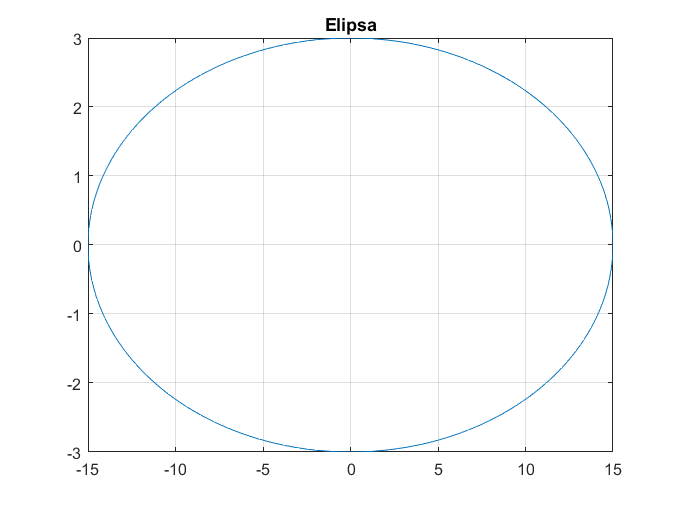

% definisanje parametara GA
N=50; pc=0.9; pm=0.001; G=0.8;%L format prvih 12 bita su x ostali su y 

a=15;
b=3;
teta=linspace(0,2*pi,200);
elipx=a*cos(teta);
elipy=b*sin(teta);
elipsa=[elipx' elipy'];
% crtanje 
figure()
plot(elipx,elipy)
grid on
title('Elipsa')

% inicijalna populacija
for i = 1:N
    tmp = rand;%odredjuje gen
    gen(i,1:L) = dec2bin(round(tmp*(2^L-1)),L);
end
% gen je matrica N x L i cine je biti cele generacije

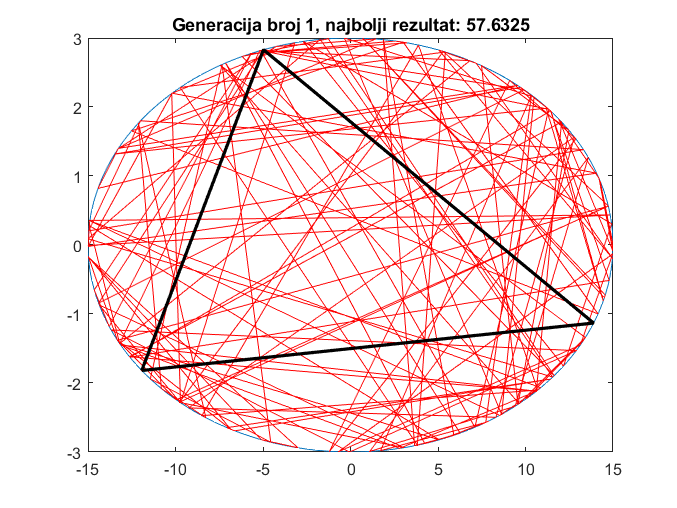

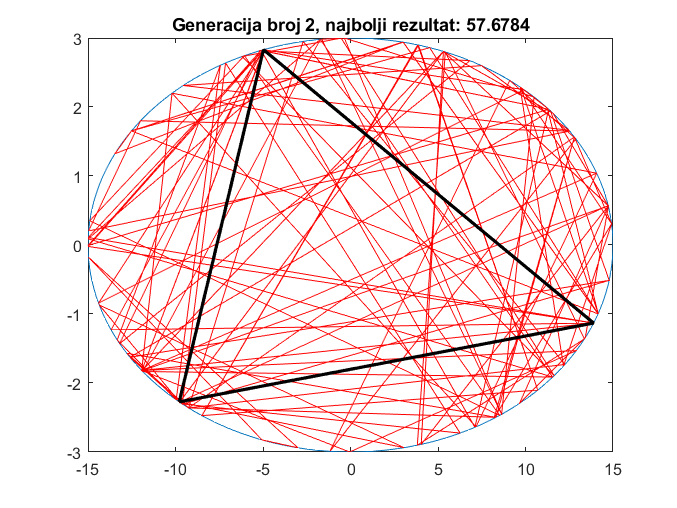

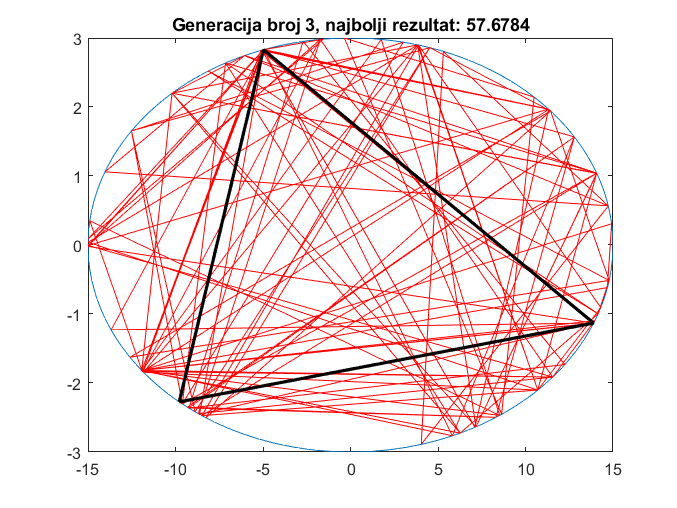

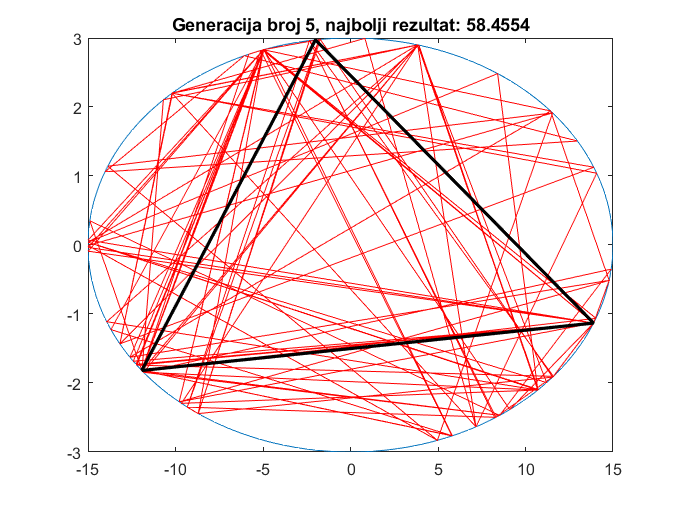

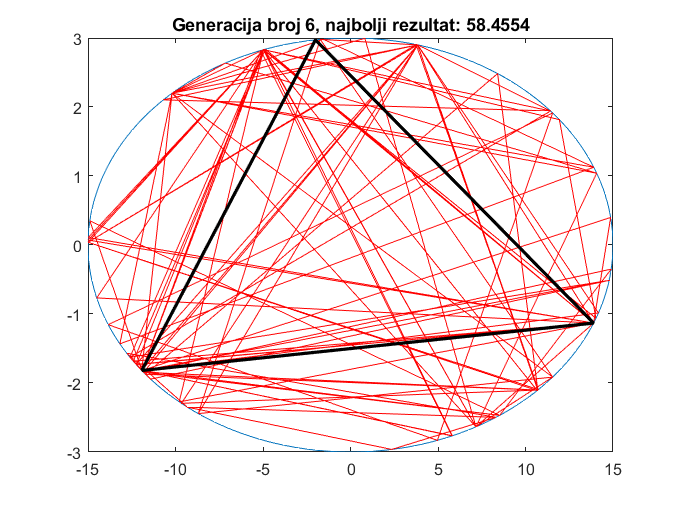

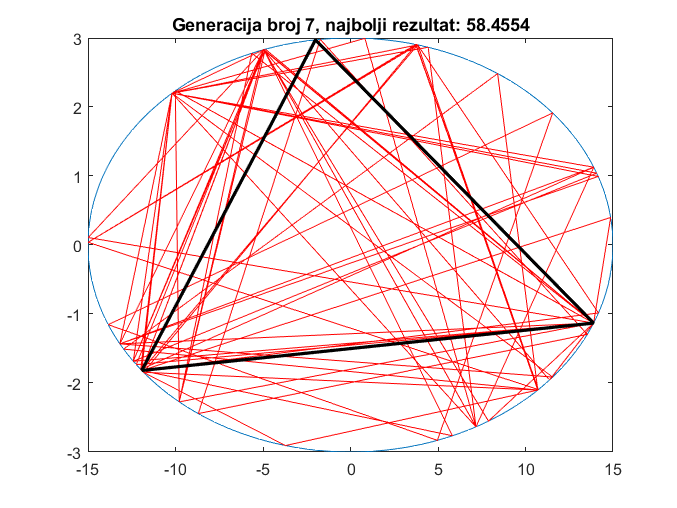

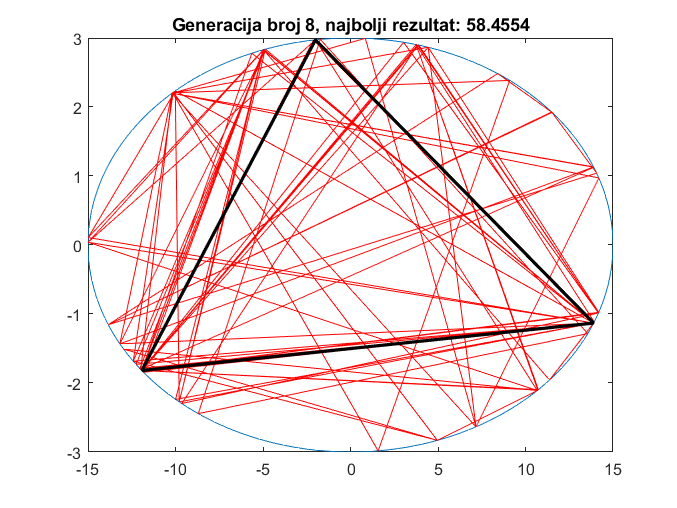

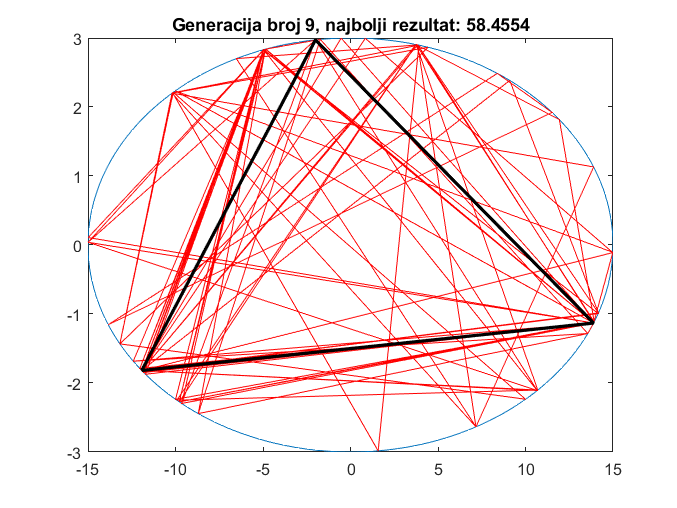


uslov = 0;
br_gen = 0;
Fmax = [];

while uslov==0
    
    br_gen = br_gen+1;
       
    % evaluacija generacije
    ugao1 = bin2dec(gen(:,1:L/3))/(2^(L/3)-1)*2*pi; 
    ugao2 = bin2dec(gen(:,L/3+1:2*L/3))/(2^(L/3)-1)*2*pi;
    ugao3 = bin2dec(gen(:,2*L/3+1:L))/(2^(L/3)-1)*2*pi;
    
    
    x1=a*cos(ugao1); y1=b*sin(ugao1);
    x2=a*cos(ugao2); y2=b*sin(ugao2);
    x3=a*cos(ugao3); y3=b*sin(ugao3);
    
    aa=sqrt((x1-x2).^2+(y1-y2).^2);% duzina stranica a
    bb=sqrt((x2-x3).^2+(y2-y3).^2);% duzina stranica b
    cc=sqrt((x1-x3).^2+(y1-y3).^2);% duzina stranica c
    s= (aa+bb+cc)/2;
    f = sqrt(s.*(s-aa).*(s-bb).*(s-cc));% izracuna

    [fmax,imax] = max(f);
    Fmax = [Fmax fmax];% Pamti napredak max
    
    % prikaz rezultata
    close all
    
    figure
    plot(elipx,elipy)
    hold all
    plot([x1 x2 x3 x1]',[y1 y2 y3 y1]','r')
    plot([x1(imax) x2(imax) x3(imax) x1(imax)]',[y1(imax) y2(imax) y3(imax) y1(imax)]','k','LineWidth',2)
    hold off
    title((['Generacija broj ' num2str(br_gen) ', najbolji rezultat: ' num2str(max(f))]));
    hold off

    
    pause
    
    % formiranje nove generacije
    gen_staro = gen;
    clear gen
    
    N_reprodukcija = round((1-G)*N);
    N_ukrstanje = N-round((1-G)*N);
    if mod(N_ukrstanje,2)==1
        N_ukrstanje = N_ukrstanje+1;
        N_reprodukcija = N_reprodukcija-1;
    end
    
    % reprodukcija tockom ruleta
    cc = cumsum(f); %kumulativna suma
    [max_v,max_i]=max(f);
    gen(1,1:L)=gen_staro(max_i,1:L);%prvi hromozom uzimamo najbolji hromozom 
    %od predhodne gen i zelim da ga sacuvam
    
    %vrtimo rulet
    for i = 2:N_reprodukcija
        pom = rand*cc(N); %mesto gde se rulet zaustavi
        pom_i = find(sign(cc-pom)==1,1,'first');% nadji prvu kojoj je cc-pom pozitivna 
        gen(i,1:L) = gen_staro(pom_i,1:L); % uzmi taj gen i prebaci ga u sl gen 
    end
    
    % formiranje novih jedinki ukrstanjem
    for i = 1:N_ukrstanje/2
        
        % izbor roditelja
        pom = rand*cc(N);
        pom_i = find(sign(cc-pom)==1,1,'first');
        roditelj1 = gen_staro(pom_i,1:L);
        
        pom = rand*cc(N);
        pom_i = find(sign(cc-pom)==1,1,'first');
        roditelj2 = gen_staro(pom_i,1:L);
        
        % ukrstanje
        if rand<pc
            tacka_ukrstanja = ceil(rand*(L-1));% random delimo gen i ukrstamo
            gen(N_reprodukcija+2*i-1,1:L) = [roditelj1(1:tacka_ukrstanja) ...
                roditelj2(tacka_ukrstanja+1:L)];
            gen(N_reprodukcija+2*i,1:L) = [roditelj2(1:tacka_ukrstanja) ...
                roditelj1(tacka_ukrstanja+1:L)];
        else
            %ako se ne ukrse samo predju u next gen
            gen(N_reprodukcija+2*i-1,1:L) = roditelj1;
            gen(N_reprodukcija+2*i,1:L) = roditelj2;
        end
        
    end
    
    % mutacija
    %round(pm*N*L) treba da je veci od 1
    for i = 1:round(pm*N*L)
        N_i = ceil(rand*(N));%random gen
        L_i = ceil(rand*(L));%random bit
        gen(N_i,L_i) = num2str(1-str2num(gen(N_i,L_i))); %mutiraj
    end
    
    % uslovi za prestanak algoritma
    fs=sort(f);
    if abs(fs(N)-fs(N-10))<0.0001 || br_gen>50
        uslov=1;
    end
    
end


figure
plot(Fmax)